clc
clear

data = xlsread('Covid.xlsx')

data =          387          98        6817         957
         811         119        7628        1076
         440         112        8068        1188
         522          94        8590        1282
         728         106        9318        1388
         597         205        9915        1593
         583         180       10498        1773
        1008         106       11506        1879
         790         121       12296        2000
         678         115       12974        2115


Give no. of patterns to be trained and no of iterations(N)

P=20;
N=300 ;

Input Matrix

**Pattern vs Inputs

I=data(1:P,1:2);

 Targeted Output Matrix

**Pattern vs Outputs

TO=data(1:P,3);

Bias for hidden and output layer

%B=rand(1,2);
B=[0 0];

%learning rate & momentum coefficint
eta=0.3;
alpha=0.2;

save Inputs

load Inputs.mat
whos

  Name        Size            Bytes  Class     Attributes

  B           1x2                16  double              
  I          20x2               320  double              
  N           1x1                 8  double              
  P           1x1                 8  double              
  TO         20x1               160  double              
  alpha       1x1                 8  double              
  data       31x4               992  double              
  eta         1x1                 8  double              



l1=size(I,2);
l2=3;
l3=size(TO,2);
v=rand(l1+1,l2);  % +1 for bias(last row)
w=rand(l2+1,l3);
I=[I(1:P,:) B(1)*ones(P,1)];


for q=1:N  %NO. of iterations
    
    sumW=zeros(l2+1,l3);
    dwi=zeros(l2+1,l3);
    
    sumV=zeros(l1+1,l2);
    dvi=zeros(l1+1,l2); 
    
    sumE=zeros(1,l3);
    Hi=zeros(1,l2);
    Ho=zeros(1,l2);
    Oi=zeros(1,l3);
    Oo=zeros(1,l3);
    

 %Normalization 
 [I,TO]=normalisation(I,TO,P);

absum=0;

 for p=1:P      %loop for pattern

%Input to hidden neurons
% for j=1:l2
%     Hi(j)=B(1)*v(end,j);
%     for i=1:l1
%         Hi(j)=Hi(j)+I(p,i)*v(i,j);
%     end
% end

Hi=I(p,:)*v;

%output of hidden neurons
% for j=1:l2
%     Ho(j)=H_out(Hi(j));
% end

Ho=H_out(Hi);

%Input to output neurons
% for k=1:l3
%     Oi(k)=B(2)*w(end,k);
%     for j=1:l2
%         Oi(k)=Oi(k)+Ho(j)*w(j,k);
%     end
% end
Ho(l2+1)=B(2);
Oi=Ho*w;

%Output of output neurons
% for k=1:l3
%     Oo(k)=O_out(Oi(k));
% end

Oo=O_out(Oi);

Ho(l2+1)=B(2);
for j=1:l2+1
    for k=1:l3
        sumW(j,k)=sumW(j,k)+(-1)*(TO(p,k)-Oo(k))*(1+Oo(k))*(1-Oo(k))*Ho(j);
    end
end

%I(p,l1+1)=B(1);
Ho(l2+1)=B(2);
for i=1:l1+1
    for j=1:l2
        for k=1:l3
             sumV(i,j)=sumV(i,j)+(-1)*(TO(p,k)-Oo(k))*(1+Oo(k))*(1-Oo(k))*w(j,k)*Ho(j)*(1-Ho(j))*I(p,i);
        end
       
    end
end

%Error calculations
for k=1:l3
    absum=absum+abs(Oo(k)-TO(p,k));
end



end         %end of Pattern loop



dw=(-eta/P)*sumW;
w=w+(dw)+alpha*dwi;
dwi=dw;

dv=(-eta/P)*sumV;
v=v+(dv)+alpha*dvi;
dvi=dv;


aE(q)=absum/P;

end    %end of Iteration loop

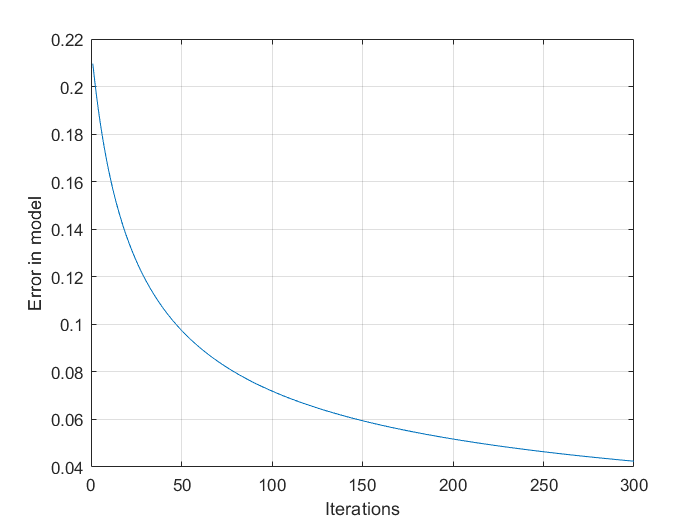

plot(aE)
hold on
%plot(E2)
%legend('Error of O/p 1','Erroe of O/p 2')
xlabel('Iterations')
ylabel('Error in model')
grid on
hold off

## ***Testing Model***

test_I = data(21:end,1:2);
test_TO = data(21:end,3);

P=size(test_I,1);
test_I=[test_I(1:P,:) B(1)*ones(P,1)];


kk= [test_I test_TO];

%Normalization 
[test_In,test_TOn]=normalisation(test_I,test_TO,P);

for p=1:P
    
    Hi=test_In(p,:)*v;
    Ho=H_out(Hi);
    Ho(l2+1)=B(2);
    Oi=Ho*w;
    Oo=O_out(Oi);
    
    Min=min(kk(p,:));
    Max=max(kk(p,:));
    
    test_o(p) = Oo*(Max-Min)+Min;
end

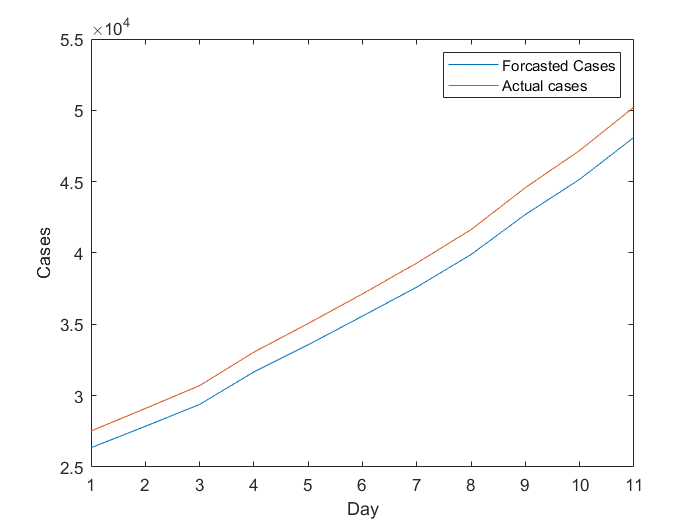

plot(test_o)
hold on
plot(test_TO)
ylabel('Cases')
xlabel('Day')
legend('Forcasted Cases','Actual cases')
hold off

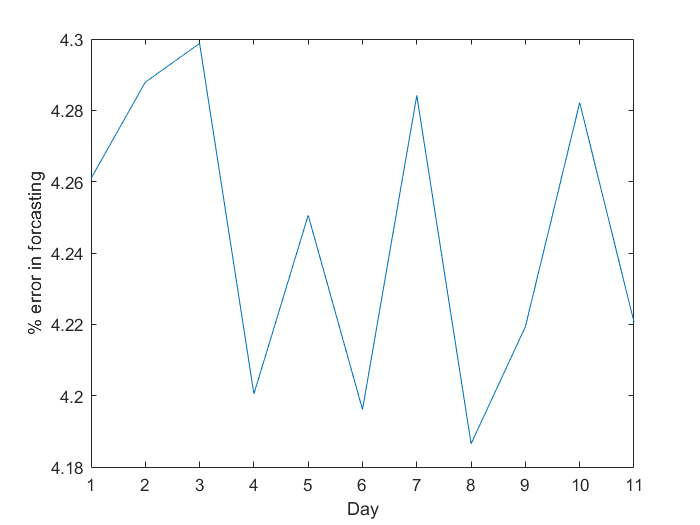

forcastings_error = 100*abs(test_o'-test_TO)./test_TO;
plot(forcastings_error)
ylabel('% error in forcasting')
xlabel('Day')